# **Arrays and Matrices**

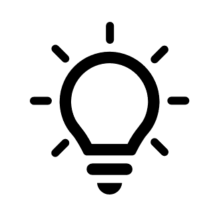 Where do I find MATLAB? [Here](https://www.mathworks.com/academia/tah-portal/wits-university-40783970.html)!

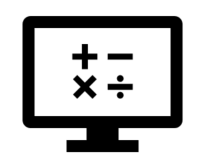 Do I have to have MATLAB installed on my computer right now? No, you can use  [MALAB Online](https://matlab.mathworks.com/)!

## Recap of Week 1: Introduction and Data Types

Last week, we learnt about:

- What programming is

- What MATLAB is

- Data types

- Variables and Commands

- Mathematical Functions

- MATLAB Live Editor

This week we have split the content into two parts. We begin with Part 1: Arrays and Matrices, which covers the following: 

- What arrays and matrices are

- Creating arrays

- Indexing into arrays 

- Concatenation of arrays

- Operating with function on arrays

## Arrays and Matrices 

### Introduction to arrays and matrices

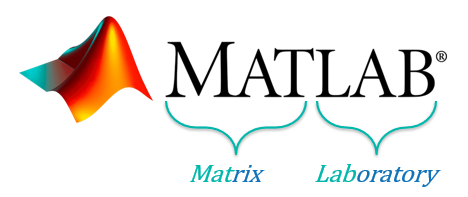

The name MATLAB is an abbreviation of "MATrix LABoratory". MATLAB was designed to work with matrices as the fundamental unit of data. A matrix is regular two-dimensional grid, or table, of numbers, with rows and/or columns.

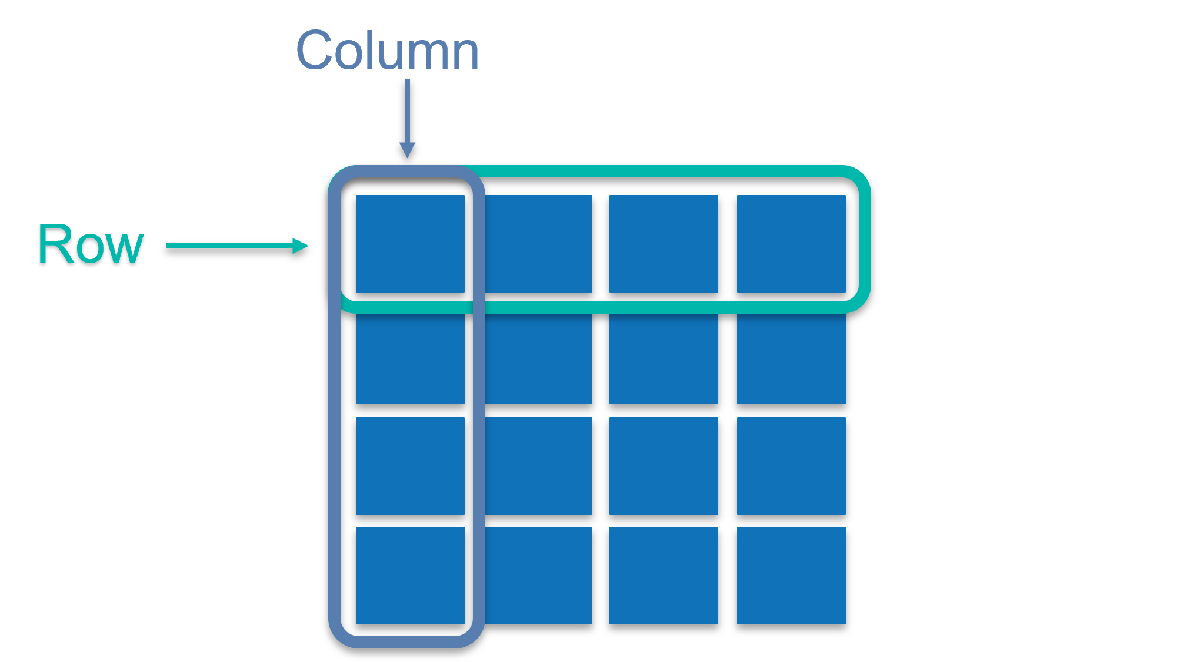

They can come in many shapes and sizes,  

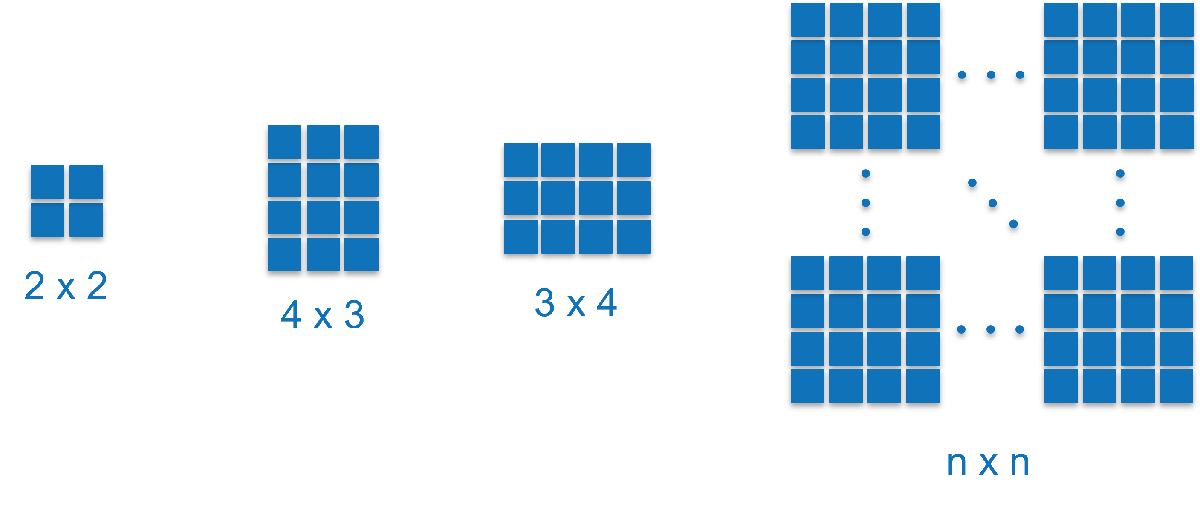

and we have a special case when there is only a single row and/or column. Let us consider what MATLAB understands [arrays and matrices](https://www.mathworks.com/help/matlab/learn_matlab/matrices-and-arrays.html) to be. Refer to the image below, beginning at the smallest, inner most oval and working our way to the largest, outer most oval. When there is only one row and one column, we have a scalar value. A scalar value would be any numerical value that includes the digits 0 to 9, in a positive or negative form, for example `5` or `-5`. 

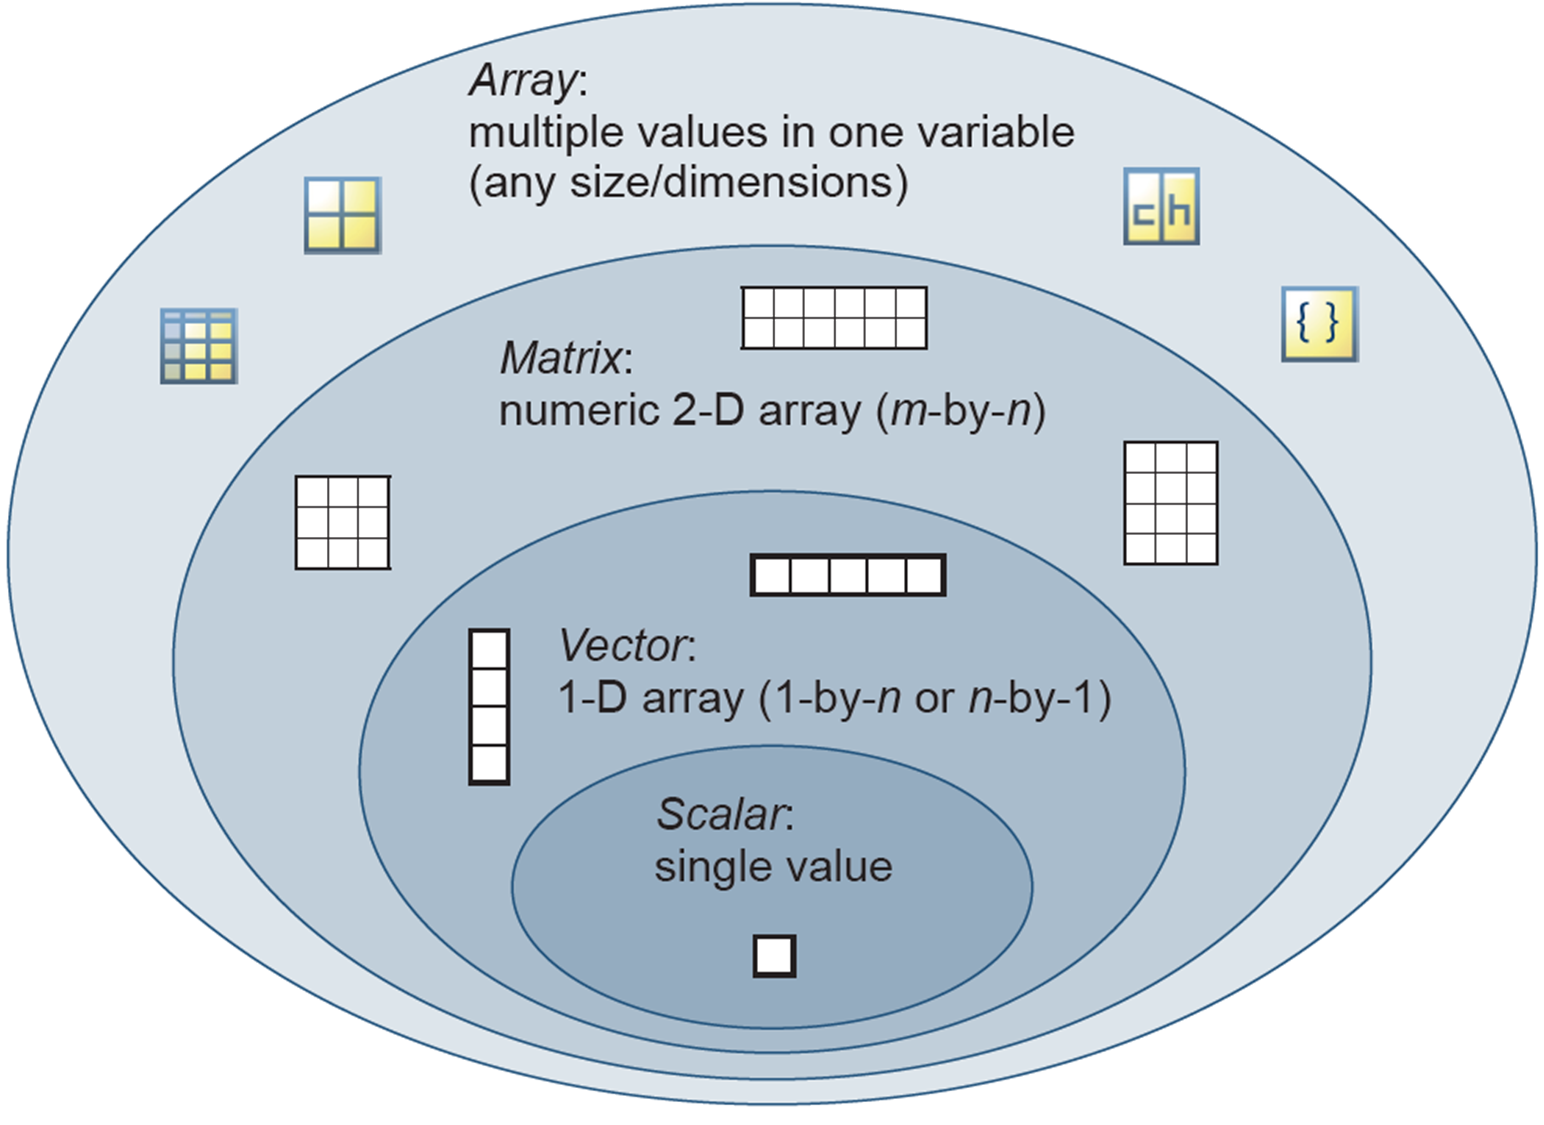

When there is a single row or column, we have a vector. A vector is a collection of scalar values/elements arranged in row or column form and is also known as a 1-D numeric array. Combining row or column vectors results in a matrix, which is also referred to as a 2-D numeric array. When you wish to include data that is not in numeric form, we refer to the variable simply as an array. An array can have multiple data types and values in one variable and can be of any size/dimension. Examples of arrays include: 

- Numeric arrays

- Character arrays

- Cell arrays

- Tables

You interact with applications of matrices and arrays in your everyday life, with images being likely the most common one. An image is stored in electronic devices as arrays or matrices, where each pixel in the image is represented by a single element in an 2-dimensional array or matrix. For grayscale images, only one matrix is stored with element values between 0 (white) and 1 (black). Colour images are a collection of three array/matrix layers based on RGB code, i.e. a matrix for Red, Green, and Blue coded numerical values. 

Now you try! Run the following code will import a stock image from MATLAB, convert it to grayscale, and display it. 

A = imread('street1.jpg');
B = rgb2gray(A);
imshow(B)

Take a look in the workspace at the variables created in the code above. You'll notice that A is an array with three matrices (one for each RGB layer) with 480 rows and 640 columns each, and B is a matrix with 480 rows and 640 columns. The number of pixels in an image is determined by taking the number of rows and multiplying it by the number of columns, i.e. for this image there are `307 200` pixels. 

### Array creation

**Creating vectors by specifying each element individually**

We use square brackets, $\left\lbrack \right\rbrack$, in MATLAB to denote numeric arrays. There are a few ways of creating an array in MATLAB. As MATLAB's convention defines observations as rows and columns as variables of the observations, let us begin by creating some row vectors. To separate values in a row vector you can either use a space or a comma:

a_1 = [1 2 3 4]

a_1 =      1     2     3     4


a_2 = [1, 2, 3, 4]

a_2 =      1     2     3     4


Note: MATLAB interprets a comma as a separator and not a decimal point. 

To create a column vector, simply use a semi-colon to separate the values:

a_3 = [1; 2; 3; 4]

a_3 =      1
     2
     3
     4


You can interchange between row and column vectors by transposing between one and the other. This is done by including an inverted comma after the closing square bracket, for example

a_4 = [1; 2; 3; 4]'

a_4 =      1     2     3     4


Now you try! Create a row vector called `x_1` with the values `2`, `4`, `6`, and `8`.

**Creating vectors of equally spaced element values**

Typing out each element of a vector can be tedious and time consuming. In the case where you require a vector to be created with equally spaced element values, there are two approaches available. 

Method 1: Using the notation `var = start : step size : end`

a_5 = 1:2:10
a_6 = 10:-2:1

We use the colon operator to create regularly spaced vectors, index into arrays, and define the bounds of a `for` loop. For now, we are considering its application in vector creation, but we will get to its other applications later on. 

You will notice that the specified "end" value is not necessarily the last element's value when using this approach, as with the output for variable `a_6.` This is a distinct difference between this approach and the following one. Another important property of this approach is that if you do not specify the "step size" in this notation, MATLAB will assume you are requesting for a step size of 1.

a_7 = 1:4

a_5 =      1     3     5     7     9


Now you try! Create a row vector `x_3` that spans from $-2\pi$ to $2\pi$ equally spaced of `0.2`

a_6 =     10     8     6     4     2


Method 2: Using the built in function `var = linspace(start, end, number of elements)`

a_8 = linspace(1,10,5)

a_7 =      1     2     3     4


This approach gives the user direct control of the number of points/elements and ensures that the last element of the vector is the value specified by the user. MATLAB automatically calculates what step size is required given the user's input to the function. It is important to note that if the number of points/elements is not specified by the user, MATLAB will assume a default value of 100 points is required.

Now you try! Create a row vector `x_4` that spans from `0` to `10` with `100` elements equally spaced.

**Creating vectors using other built-in functions**

There are a few built in functions you can leverage for creating vectors and matrices in MATLAB. This subsection will cover 3 examples of such functions, which will come in handy when trying to avoid computationally expensive iterative scripts/loops. Let us begin by creating a vector with all elements being the value `1,` and then a second vector where all elements have a value of `0`. Both of these functions expect two inputs, one for the number of rows, `r,` and the next for the number of columns, `c,` i.e. `var = ones(r, c) `or `var = zeros(r, c)`

b_1 = ones(1,5)
b_2 = zeros(1,5)

Next, let us create a vector or values drawn from a uniform distribution in the interval `(0, 1)`. The function `rand` is used to do this, following the same notation as the functions `ones` and `zeros`, `var = rand(r, c)`

b_3 = rand(1,5)

a_8 =    1.000000000000000   3.250000000000000   5.500000000000000   7.750000000000000  10.000000000000000


Now you try! Create a row vector `x_5` that spans from `0` to `10` with `100` elements equally spaced.

### **Array Indexing**

In this subsection, we will cover how to index into arrays to extract or reassign one or more elements. We begin by initialising an arbitrary variable matrix, `A:`

syms a11 a12 a13 a21 a22 a23 a31 a32 a33

Aside: You can look up the Symbolic Math Toolbox for more details on the above command however, this will be covered in a future section of this course.

A =[a11 a12 a13; a21 a22 a23; a31 a32 a33]

b_1 =      1     1     1     1     1


To index into a matrix, specify the row, `r`, and column, `c`, numbers of interest using the notation `MatrixName(r, c).` Let us access the element in the first row and the second column of the above matrix, `A` and assign it to a new workspace variable.

NewWorkspaceVariable_1 = A(1,2)

b_2 =      0     0     0     0     0


To extract an entire row or column, use a colon, `:`, instead of specifying the column or row number, for example let us extract the all the columns of row 1:

NewWorkspaceVariable_2 = A(1,:)

b_3 =    0.814723686393179   0.905791937075619   0.126986816293506   0.913375856139019   0.632359246225410


In a similar way, let us extract all rows of the second column:

NewWorkspaceVariable_3 = A(:,2)

When referencing rows or columns, MATLAB interprets a colon as **all** the rows or columns (as seen above). Sometimes only specific elements of the array are required, so being able to specify this in a single command is useful. MATLAB allows referencing elements in an array by specifying the indices/positions in an array, for example let us extract the elements from column 2 until the last column, of row 1 in matrix `A`: 

NewWorkspaceVariable_4 = A(1,2:end)

You'll notice that instead of specifying the end index value, `3`, the syntax `end` was used. This is a convenient way to index the last element in an array without first determining its value, and this approach to coding assists with code readability. 

So far, we have covered how to reference from an array to create a new workspace variable. Now, we will consider how to replace/overwrite an element in an array. As we references a row and column above when extracting the element value, we now use assignment to that element value, i.e. the matrix reference will be on the left-hand side of the equals sign `MatrixName(r, c) = value`. Let us replace the element in column 3 of the first row with the value `10`: 

A(1,3)=10

$$A = \left(\begin{array}{ccc} a_{11} & a_{12} & a_{13}\\ a_{21} & a_{22} & a_{23}\\ a_{31} & a_{32} & a_{33} \end{array}\right)$$

Note: The element $a_{13}$ has now been replaced by the value `10.` This operation cannot be undone, and the only way to have a value $a_{13}$ in column 3 of the first row, is to reassign that variable to the element position. 

The assignment operation to an array row or column can also be used to remove/delete the row or column respectively, by assigning the entire row or column to an empty array `[]`. As an example, let us remove the entire first row of the matrix `A:`

A(1,:) = []

$$NewWorkspaceVariable\_1 = a_{12}$$

Now you try! Create a 3-by-3 symbolic matrix `A` as demonstrated in the beginning of the Array indexing section. 

Extract the element from the third column and second row, and assign it to the variable `x_6`.

$$NewWorkspaceVariable\_2 = \left(\begin{array}{ccc} a_{11} & a_{12} & a_{13} \end{array}\right)$$

Extract the entire third row, and assign it to the variable `x_7`.

Replace the element in third row and second column with the value `5`. 

$$NewWorkspaceVariable\_3 = \left(\begin{array}{c} a_{12}\\ a_{22}\\ a_{32} \end{array}\right)$$

### **Array concatenation**

Array concatenation is the process of combining two or more arrays into a single array. There are two ways of concatenating arrays; horizontally and vertically, both of which use the notation you learnt in the Creating vectors by specifying each element individually subsection. 

To concatenate **horizontally**, simply use the square bracket (and comma) notation used when combining elements into a row vector, i.e. `NewMatrix = [Matrix_1 Matrix_2]` or `NewMatrix = [Matrix_1, Matrix_2]`. It is important that the **number of columns is the same** for all the arrays being concatenated. Let us try this operation by horizontally concatenating a **2-by-2 matrix **`A` with a **2-by-1** matrix (**column vector**) `x`:

syms a11 a12 a21 a22 x1 x2

$$NewWorkspaceVariable\_4 = \left(\begin{array}{cc} a_{12} & a_{13} \end{array}\right)$$

Aside: You can look up the Symbolic Math Toolbox for more details on the above command however, this will be covered in a future section of this course.

A =[a11 a12; a21 a22]

$$A = \left(\begin{array}{ccc} a_{11} & a_{12} & 10\\ a_{21} & a_{22} & a_{23}\\ a_{31} & a_{32} & a_{33} \end{array}\right)$$

x = [x1; x2]
A = [A x]

The above is the result of horizontally combining the matrix `A` with the column vector `x`. 

To concatenate **vertically**, simply use the square bracket and semicolon notation used when combining elements into a column vector, i.e. `NewMatrix = [Matrix_1; Matrix_2]`. It is important that the **number of rows is the same** for all the arrays being concatenated. Let us try this operation by vertically concatenating a **2-by-2 matrix** `A` with a **1-by-2** matrix (**row vector**) `x`:

A =[a11 a12; a21 a22]

$$A = \left(\begin{array}{ccc} a_{21} & a_{22} & a_{23}\\ a_{31} & a_{32} & a_{33} \end{array}\right)$$

x = [x1 x2]
A = [A; x]

Horizontal and vertical concatenation can also be combined in a single operation as long as the dimensions match, i.e. the number of rows and columns are equal when concatenating vertically and horizontally respectively. For example, consider 3 matrices, `A`, `B`, and `C` which have the dimensions `4-by-4`, `1-by-4`, and `5-by-2` respectively. What command will combine all three matrices into a single matrix with dimensions `6-by-6`? 

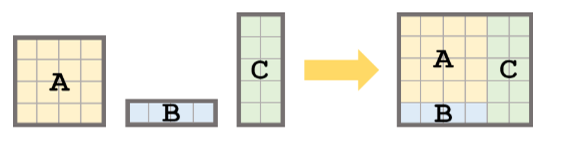

The above image illustrates graphically how this operation should take place. There is a vertical concatenation of `A` and `B`, and then a horizontal concatenation of the result with matrix `C`. Let us begin by defining the three matrices: 

syms a11 a12 a13 a14 a21 a22 a23 a24 a31 a32 a33 a34 a41 a42 a43 a44 b11 b12 b13 b14 c11 c12 c21 c22 c31 c32 c41 c42 c51 c52
A = [a11 a12 a13 a14;
     a21 a22 a23 a24;
     a31 a32 a33 a34;
     a41 a42 a43 a44];
B = [b11 b12 b13 b14];
C = [c11 c12;
     c21 c22;
     c31 c32;
     c41 c42;
     c51 c52];

As described above, concatenate matrix `A` and `B` vertically (`[A; B]`) and then horizontally concatenate that resulting matrix with matrix `C (NewMatrix = [[A; B] C]):`

NewMatrix = [[A; B] C]

Now you try! Create a matrix array, `A`, with element values `1`, `2`, `4`, and `5`, and a column vector array, `b`, with element values `3`, and `6`. Horizontally concatenate the vector array to the right-hand side of the matrix array. 

### **Operate with functions on arrays**

Many built in functions of MATLAB can be applied directly to arrays, eliminating the need for iterating through each element of an array. In this subsection we will consider basic, element-wise arithmetic, and then operate on an array with three (of many) mathematical functions.

At this point in your academic year, you have likely covered some linear algebra operations, including matrix multiplication and "division" (using the transpose of a matrix). These are different operations from element-wise multiplication and division, in that they operate on the whole row or column of the array and not just a single element position at a time. See documentation on [`mtimes`](https://www.mathworks.com/help/matlab/ref/mtimes.html) and [`mrdivide`](https://www.mathworks.com/help/fixedpoint/ref/embedded.fi.mrdivide.html) for more information on these matrix operations. Let us now demonstrate some basic, element-wise arithmetic. 

To get us started, let us define 2 vector arrays `a` and `b` with `5` equally spaced element values as follows:

a = 10:10:50

$$A = \left(\begin{array}{cc} a_{11} & a_{12}\\ a_{21} & a_{22} \end{array}\right)$$

b = 5:-1:1

$$x = \left(\begin{array}{c} x_{1}\\ x_{2} \end{array}\right)$$

Let us consider the element-wise multiplication and division of the vector arrays `a` and `b`, denoted respectively by the operators `.*` and `./` 

a.*b

$$A = \left(\begin{array}{ccc} a_{11} & a_{12} & x_{1}\\ a_{21} & a_{22} & x_{2} \end{array}\right)$$

a./b

Note that the vector arrays, `a` and `b`, have the same dimensions, and the output has the same dimensions as the input arrays. Consult the documentation for [`times`](https://www.mathworks.com/help/matlab/ref/times.html) and [`rdivide`](https://www.mathworks.com/help/matlab/ref/rdivide.html) for more information about their other operating properties.

Now you try! Consider the following 2 vector arrays, `quantity`, `price_per_pack`, which represent the number of pears in a fruit pack, and its corresponding selling price in ZAR per fruit pack, respectively. 

quantity = 2:2:8;

$$A = \left(\begin{array}{cc} a_{11} & a_{12}\\ a_{21} & a_{22} \end{array}\right)$$

price_per_pack = [10 18 25.5 30];

$$x = \left(\begin{array}{cc} x_{1} & x_{2} \end{array}\right)$$

Determine the selling price per unit (pear) when a fruit pack is chosen, i.e. use element-wise division of `price_per_pack` by `quantity`.

$$A = \left(\begin{array}{cc} a_{11} & a_{12}\\ a_{21} & a_{22}\\ x_{1} & x_{2} \end{array}\right)$$

There are many operators that can be applied directly to arrays, including trigonometric, logarithmic, and other mathematical functions. Let us demonstrate this by first creating an array of values in the interval $\left\lbrack 0,2\pi \right\rbrack$, and then operating on the array with the `sin`, `tan`, and `log` functions.

x = linspace(0,2*pi)
y_1 = sin(x)
y_2 = tan(x) 
y_3 = log(x)

Note that all 100 evaluated values of each function were generated with a single line of code. If you are unsure of whether a function can operate on an array, search for its definition in the documentation either by:

- Using the *Search Documentation* box on the top right-hand corner of the MATLAB user interface 

- Typing the function in a code section or the command window and press `F1` or right-click and select *Help on "Function"* 

If the function does not operate on an array, make use of the `arrayfun` function. See [arrayfun documentation](https://www.mathworks.com/help/matlab/ref/arrayfun.html) for more on this. 

Now you try! Create a row vector array, `x`, with 5 equally spaced element values between `-1` and `1`. Determine the absolute value of this array using the `abs` function. 

$$NewMatrix = \left(\begin{array}{cccccc} a_{11} & a_{12} & a_{13} & a_{14} & c_{11} & c_{12}\\ a_{21} & a_{22} & a_{23} & a_{24} & c_{21} & c_{22}\\ a_{31} & a_{32} & a_{33} & a_{34} & c_{31} & c_{32}\\ a_{41} & a_{42} & a_{43} & a_{44} & c_{41} & c_{42}\\ b_{11} & b_{12} & b_{13} & b_{14} & c_{51} & c_{52} \end{array}\right)$$

a =     10    20    30    40    50


b =      5     4     3     2     1


ans =     50    80    90    80    50


ans =      2     5    10    20    50


x =                    0   0.063466518254339   0.126933036508679   0.190399554763018   0.253866073017357   0.317332591271696   0.380799109526036   0.444265627780375   0.507732146034714   0.571198664289053   0.634665182543393   0.698131700797732   0.761598219052071   0.825064737306410   0.888531255560750   0.951997773815089   1.015464292069428   1.078930810323767   1.142397328578107   1.205863846832446   1.269330365086785   1.332796883341124   1.396263401595463   1.459729919849803   1.523196438104142   1.586662956358482   1.650129474612821   1.713595992867160   1.777062511121499   1.840529029375839   1.903995547630178   1.967462065884517   2.030928584138856   2.094395102393195   2.157861620647535   2.221328138901874   2.284794657156213   2.348261175410553   2.411727693664892   2.475194211919231   2.538660730173570   2.602127248427909   2.665593766682249   2.729060284936588   2.792526803190927   2.855993321445267   2.919459839699606   2.982926357953945   3.046392876208284   3.10985939446

y_1 =                    0   0.063423919656565   0.126592453573749   0.189251244360410   0.251147987181079   0.312033445698487   0.371662455660328   0.429794912089172   0.486196736100469   0.540640817455598   0.592907929054640   0.642787609686539   0.690079011482112   0.734591708657533   0.776146464291757   0.814575952050336   0.849725429949514   0.881453363447582   0.909631995354518   0.934147860265107   0.954902241444074   0.971811568323542   0.984807753012208   0.993838464461254   0.998867339183008   0.999874127673875   0.996854775951942   0.989821441880933   0.978802446214779   0.963842158559942   0.945000818714669   0.922354294104581   0.895993774291336   0.866025403784439   0.832569854634771   0.795761840530832   0.755749574354258   0.712694171378863   0.666769000516292   0.618158986220605   0.567059863862771   0.513677391573407   0.458226521727411   0.400930535406614   0.342020143325669   0.281732556841430   0.220310532786541   0.158001395973350   0.095056043304183   0.031727933

y_2 =                    0   0.063551870131957   0.127619173712647   0.192734202481280   0.259464150133964   0.328431671978864   0.400339609375427   0.476002081968643   0.556385057721042   0.642660977168331   0.736284400807852   0.839099631177280   0.953498074083850   1.082655149869913   1.230898709667527   1.404303506448192   1.611692685864835   1.866414037471700   2.189694562989681   2.617494887021388   3.216021266268220   4.122056142744510   5.671281819617700   8.966569877071668  20.992583461395508 -63.020068499101868 -12.578616007997889  -6.955152771773481  -4.779153215378824  -3.617023921461539  -2.889310249556724  -2.387384317195195  -2.017701283673776  -1.732050807568878  -1.503050546361892  -1.313984662781559  -1.154061520533010  -1.015993849343953  -0.894674368013107  -0.786408692179858  -0.688449661733010  -0.598703172636655  -0.515535831093197  -0.437645272406344  -0.363970234266203  -0.293626492938367  -0.225859960141265  -0.160011315925730  -0.095488422273612  -0.031743915

y_3 =                 -Inf  -2.757242783725244  -2.064095603165299  -1.658630495057135  -1.370948422605354  -1.147804871291144  -0.965483314497189  -0.811332634669931  -0.677801242045408  -0.560018206389025  -0.454657690731199  -0.359347510926874  -0.272336133937244  -0.192293426263708  -0.118185454109986  -0.049192582623034   0.015345938514537   0.075970560330972   0.133128974170920   0.187196195441196   0.238489489828747   0.287279653998179   0.333799669633071   0.378251432203905   0.420811046622701   0.461633041142956   0.500853754296238   0.538594082279085   0.574961726449959   0.610053046261230   0.643954597936911   0.676744420759902   0.708493119074482   0.739264777741236   0.769117740890917   0.798105277764169   0.826276154730866   0.853675128918980   0.880343376001141   0.906318862404402   0.931636670388692   0.956329282979063   0.980426834558124   1.003957331968318   1.026946850193017   1.049419706045075   1.071398612763851   1.092904817984814   1.113958227182646   1.134577514

## What we've covered this week in part 1: Arrays and Matrices

This week in part 1, we learnt about: 

- What arrays and matrices are

- Creating arrays

- Indexing into arrays 

- Concatenation of arrays

- Operating with function on arrays

In the next part of this week's content, we will be learning about relational and logical operators, covering the following sub-topics: 

- Introduction to decision making with operators 

- Relational operators

- Logical operators

## **PowerPoint Presentation**

- [Week_2_Part_1_Arrays_and_Matrices.pptx](matlab:open('./Week_2_Part_1_Arrays_and_Matrices.mlx'))

## Extra resources

- [Documentation: MATLAB Fundamentals](https://matlabacademy.mathworks.com/artifacts/quick-reference.html?course=mlbe&release=R2020b&language=en&) 

- [Video: How to Make a Vector in MATLAB](https://www.mathworks.com/videos/making-a-vector-the-matlab-way-97252.html?s_tid=srchtitle)

- [Video: How to Insert Data Into a Vector in MATLAB](https://www.mathworks.com/videos/inserting-data-into-a-vector-in-matlab-97214.html?s_tid=srchtitle)

- [Documentation: Removing Rows or Columns from a Matrix](https://www.mathworks.com/help/matlab/math/removing-rows-or-columns-from-a-matrix.html)

- [Video: Working with Arrays in MATLAB](https://www.mathworks.com/videos/working-with-arrays-in-matlab-69022.html?s_tid=vid_pers_recs)

- [Video: Indexing Columns and Rows](https://www.mathworks.com/videos/row-and-column-indexing-97492.html?s_tid=vid_pers_recs)

- [Documentation: Matrices and Arrays - Functions](https://www.mathworks.com/help/matlab/referencelist.html?type=function&category=matrices-and-arrays&s_tid=CRUX_topnav)

- [MATLAB Fundamentals Self-paced Course](https://matlabacademy.mathworks.com/details/matlab-fundamentals/mlbe)

- [Self-Paced Online Courses](https://matlabacademy.mathworks.com/)

## References

- [Documentation: MATLAB Fundamentals](https://matlabacademy.mathworks.com/artifacts/quick-reference.html?course=mlbe&release=R2020b&language=en&) 

- [Image Compression with Low-Rank SVD](https://www.mathworks.com/help/matlab/math/image-compression-with-low-rank-svd.html)

***Copyright 2022 The MathWorks, Inc. & Opti-Num Solutions (Pty) Ltd. ***